# Lab 3

Francesca Bennett

Collaborators: Taylor Prewitt, Natalie Shen

close all; clear all;


## Problem 1

%bad data points
b=[10., 10.3, 2.1, 0., 0., 15.6, 22.3, 12.7];

%array of 100,000 random good data points
Dist1 = makedist('Normal','mu', 0,'sigma',0.4);
a=normrnd(12,.4,[1,100000]);



**Part 1.A.1: Plots**


subplot(2,1,1);
hf1=histfit(a,100);
set(hf1(1),'FaceColor',"blue");
xlim([11,13]);
title("Histogram, Plain Random Data");

%a = transpose((11.6 + (12.4-11.6).*rand(100000,1)));
A=[a b];

subplot(2,1,2)
hf2=histfit(A,1000)

hf2 =   2×1 graphics array:

  Bar
  Line


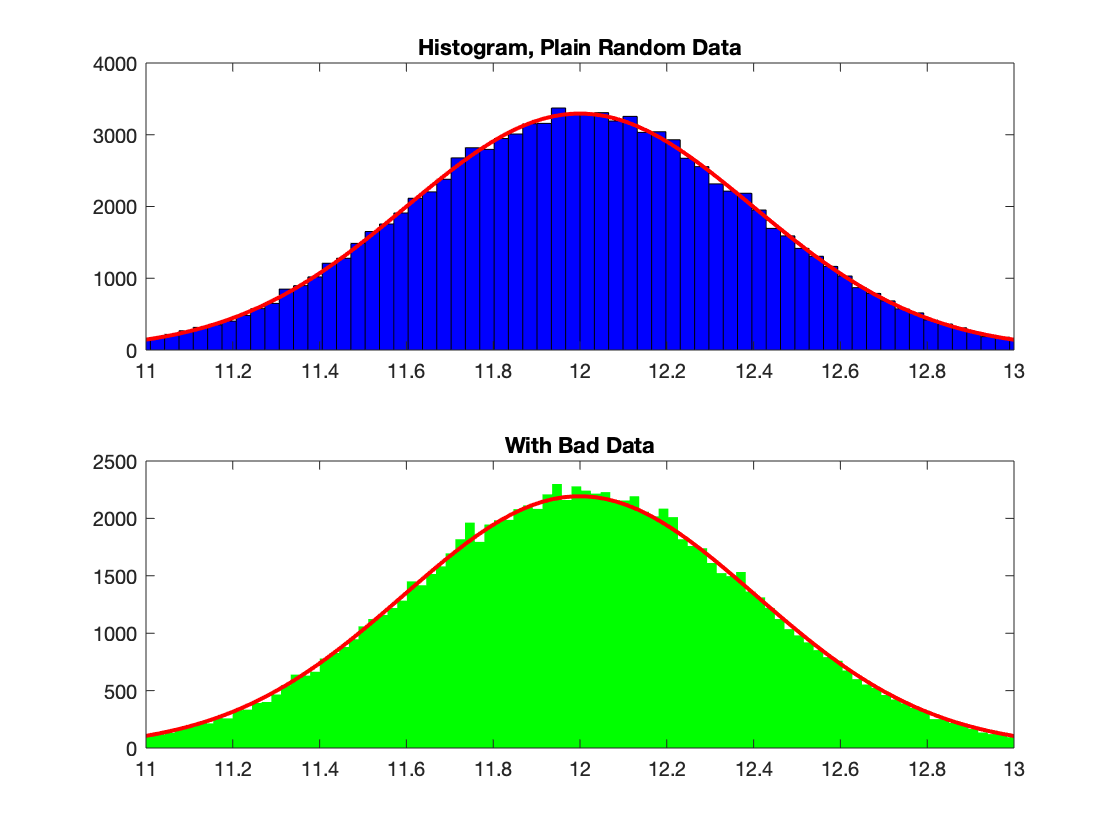

set(hf2(1),'FaceColor',"green")
xlim([11,13])
title("With Bad Data")


subplot(1,1,1)
hf3=histfit(A,100)

hf3 =   2×1 graphics array:

  Bar
  Line


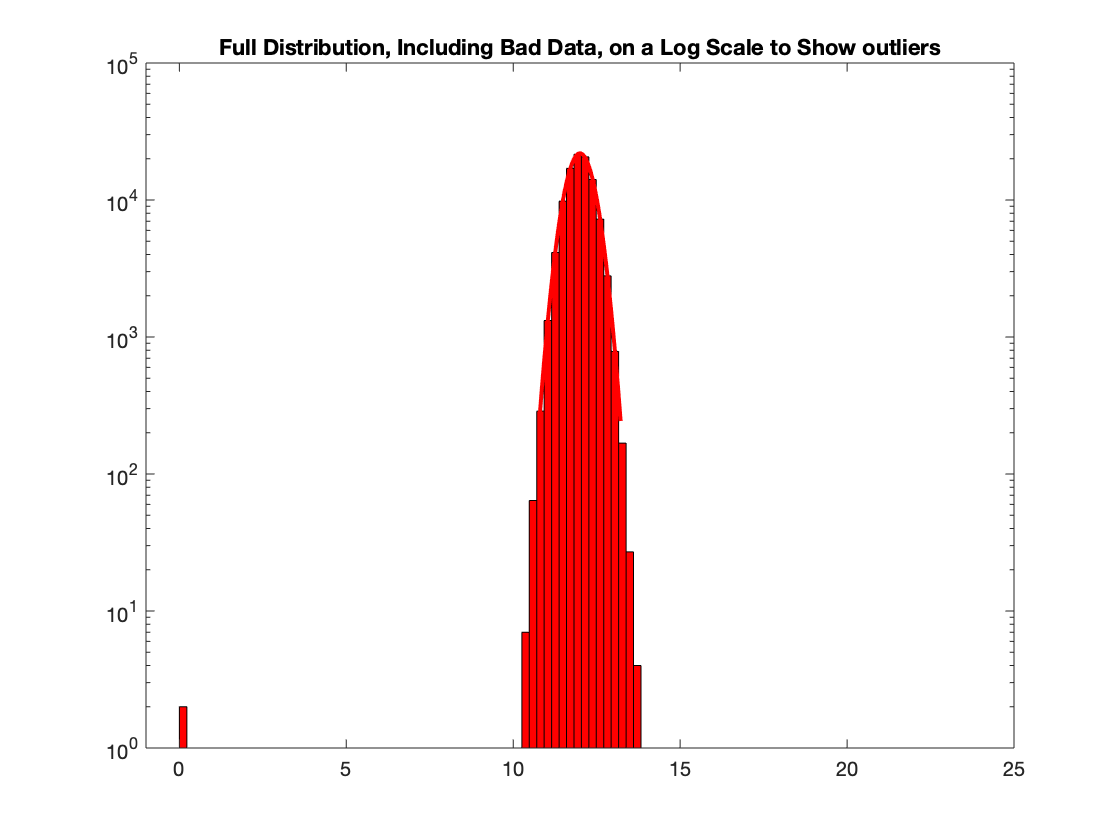

set(hf3(1),'FaceColor',"red")
xlim([-1,25])
set(gca,'YScale','log')
title("Full Distribution, Including Bad Data, on a Log Scale to Show outliers")


% title("With Bad Data")
% hold on
% plot([0,15.6,22.3],[2,1,1],'r*','LineWidth',2,'MarkerSize',15)


Old Code

%OLD CODE
% %histogram
% %subplot(2, 1, 1)
% histogram(A,150,'FaceColor',"green")
% title("Histogram")
% 
% %histogram with focus around majority of values
% %subplot(2, 1, 2)
% histogram(A,100,'BinLimits',[11,13],'FaceColor',"green")
% set(gca,'YScale','log')
% title("Refined Histogram")
% 
% %auto method
% %subplot(1, 1, 3)
% histogram(A,'BinMethod','auto','BinLimits',[11,13],'FaceColor',"green")
% 
% %histfit
% hf=histfit(A,1000)
% set(hf(1),'FaceColor',"yellow")
% xlim([11,13])
% 
% hf=histfit(a,1000)
% set(hf(1),'FaceColor',"blue")
% xlim([11,13])

%NEW CODE


**Part 1.A.2: Statistical Question**

*What data points fall outside of 2 sigma of the mean of 12 Kelvin?*

**Part 1.A.3: Representation of Question as Math**

?<2 sigma<?

**Part 1.A.4: Truth Table**

Data is either an outlier, or not. One axis is the true label, and the other axis is if it is correct or not. Every point has a true label: bad or not.

%parameter value???
mu = 0;
s=2;

%Not sure which to use!
%gives prob of A falling outside of sigma 2??
pdf1 = pdf('Normal',A,mu,s)

pdf1 =     0.0298    0.0187    0.2348    0.1586    0.0359    0.0389    0.0040    0.0525    0.0294    0.0202    0.0115    0.2710    0.1094    0.0341    0.0041    0.0865    0.2306    0.0364    0.0155    0.0115    0.1285    0.0909    0.1233    0.0139    0.0552    0.0738    0.0433    0.0048    0.0224    0.0189    0.0435    0.0102    0.0224    0.1226    0.0261    0.0862    0.1018    0.0284    0.1761    0.0055    0.0078    0.0237    0.0017    0.0184    0.0213    0.0396    0.0144    0.0087    0.0905    0.0162



%or THIS gives prob of A falling outside of sigma 2??
cdf1 = cdf('Normal',A,mu,s)

cdf1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000




other = icdf('Normal',pdf1,mu,s)

other =   -11.6357  -11.7899  -10.9249  -11.0634  -11.5737  -11.5465  -12.2867  -11.4446  -11.6401  -11.7651  -11.9503  -10.8739  -11.1930  -11.5908  -12.2806  -11.2741  -10.9313  -11.5686  -11.8527  -11.9507  -11.1370  -11.2568  -11.1514  -11.8876  -11.4280  -11.3288  -11.5104  -12.2304  -11.7304  -11.7874  -11.5089  -11.9900  -11.7315  -11.1533  -11.6806  -11.2754  -11.2179  -11.6524  -11.0266  -12.1856  -12.0757  -11.7116  -12.5525  -11.7958  -11.7482  -11.5404  -11.8775  -12.0400  -11.2584  -11.8383



other2 = icdf('Normal',cdf1,mu,s)

other2 =    12.0064   12.1599   11.2978   11.4359   11.9446   11.9175   12.6547   11.8159   12.0107   12.1353   12.3197   11.2469   11.5652   11.9616   12.6486   11.6460   11.3042   11.9396   12.2225   12.3201   11.5094   11.6288   11.5237   12.2572   11.7994   11.7005   11.8815   12.5986   12.1007   12.1574   11.8801   12.3593   12.1018   11.5256   12.0511   11.6473   11.5899   12.0230   11.3992   12.5540   12.4446   12.0820   12.9192   12.1658   12.1184   11.9114   12.2472   12.4090   11.6303   12.2082






%twice to get the point, for what happens to be a normal
%this one reflects the graphs
%because the actual dist happens to be a normal dist already
prob2 = icdf('Normal',A,0,s)

prob2 =    NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


**Part 1.B: Filter Catching Good Data**

How does lost good data depend on the statistical threshold?

Is this a predictable quantity?

**Part 1.C: Is there Commission?**

Is there any bad data that got it?

Was this avoidable?

How does this depend on the threshold?

Problem 2

Current time stamp: approx 3 hours on Tues, at least 1 hour today